**Exercise 5 part (iii)a**

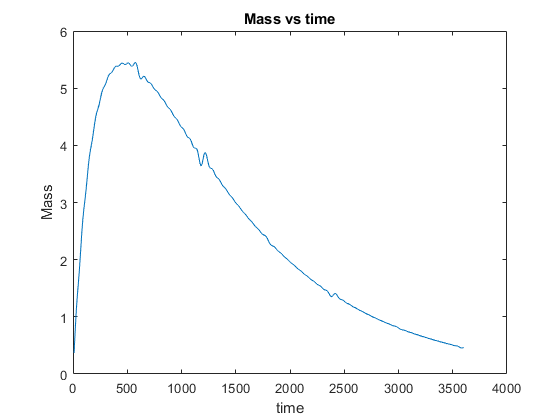



n=10;
T=3600; dt=10; nt=T/dt;
M=zeros(1,nt); t=zeros(1,nt);
for i=1:nt
    t(i)=i*dt;
    f=@(x)tank_conc(x,t(i));
    zmax=@(x)tank_height(x,t(i));
    a={-2,-2,0};
    b={2,2,zmax};
    M(i)=gsimp(f,a,b,n);
end
plo=plot(t,M);
xlabel('time')
ylabel('Mass')
title('Mass vs time')

**Exercise 5 part (iii)b**

Calculating timed average mass:

a={-2,-2,0,0};
b={2,2,T,@tank_height2};
f=@tank_conc2;
n = 10;
MT=gsimp(f,a,b,n);
fprintf('Average mass in the tank through 1 hour is %g  Kg\n',MT/T);

Average mass in the tank through 1 hour is 2.55294  Kg


function [f]=tank_conc(x,t)
% use notation x = x(1); y=x(2); z=x(3) etc...
C0=0.1; k=0.001;
f=C0*exp(-k*t)*(x(1)^2+x(2)^2)/sqrt(x(3)^2+1);
end

function [h] = tank_height(x,T)
A=pi*4;
h=gsimp(@qfunc,0,T,100)/A;
end

function [q] = qfunc(t)
Q0=0.1; omega=pi/6;
q=Q0*(1+sin(omega*t));
end
% multi-dimensional simpson main calling function
% goes from outer to inner (i.e., x to z).
function [I] = gsimp(f,a,b,n)
m=length(a); x=zeros(1,m); k=1;
% convert limits to cell array if numbers are given
if (isnumeric(a))
    a=num2cell(a);
end
if (isnumeric(b))
    b=num2cell(b);
end
% call recursive integration function
I=ksimp(f,x,a,b,n,k);
end

% recursive simpson function
function [I] = ksimp(f,x,a,b,n,k)
I=0; m=length(a);
if isnumeric(a{k})
    ak=a{k};
else
    ak=feval(a{k},x);
end
if isnumeric(b{k})
    bk=b{k};
else
    bk=feval(b{k},x);
end
h =(bk-ak)/n;
for i=0:n
    x(k)=ak+i*h;
    if (k == m)
        if (i == 0 || i == n)
            I=I+feval(f,x);
        elseif (mod(i,2) == 1)
            I=I+4*feval(f,x);
        elseif (mod(i,2) == 0)
            I=I+2*feval(f,x);
        end
    else
        if (i == 0 || i == n)
            I=I+feval(@ksimp,f,x,a,b,n,k+1);
        elseif (mod(i,2) == 1)
            I=I+4*feval(@ksimp,f,x,a,b,n,k+1);
        elseif (mod(i,2) == 0)
            I=I+2*feval(@ksimp,f,x,a,b,n,k+1);
        end
    end
end
I=I*h/3;
end


%Part b
function [f]=tank_conc2(X)
% use notation x = x(1); y=x(2); z=x(3) etc...
C0=0.1; k=1e-3; x=X(1); y=X(2); t=X(3); z=X(4);
f=C0*exp(-k*t)*(x^2+y^2)/sqrt(z^2+1);
end

function [h] = tank_height2(x)
A=4*pi; T = x(3); n = 100;
h=msimp(@qfunc2,0,T,n)/A;
end

function [q] = qfunc2(t)
Q0=0.1; w=pi/6;
q=Q0*(1+sin(w*t));
end

function [I] = msimp(f,a,b,n)
m=length(a); x=zeros(1,m); k=1;
I=ksimp2(f,x,a,b,n,k);
end

% recursive simpson function
function [I] = ksimp2(f,x,a,b,n,k)
I=0; m=length(a);
h=(b(k)-a(k))/n;
for i=0:n
    x(k)=a(k)+i*h;
    if (k == m)
        if (i == 0 || i == n)
            I=I+feval(f,x);
        elseif (mod(i,2) == 1)
            I=I+4*feval(f,x);
        elseif (mod(i,2) == 0)
            I=I+2*feval(f,x);
        end
    else
        if (i == 0 || i == n)
            I=I+feval(@ksimp,f,x,a,b,n,k+1);
        elseif (mod(i,2) == 1)
            I=I+4*feval(@ksimp,f,x,a,b,n,k+1);
        elseif (mod(i,2) == 0)
            I=I+2*feval(@ksimp,f,x,a,b,n,k+1);
        end
    end
end
I=I*h/3;
end
